myvoice=audiorecorder(8000,24,1);
disp('Start to speak')

Start to speak


recordblocking(myvoice,3)
disp('End of recording')

End of recording


play(myvoice)

ans =   audioplayer with properties:

       SampleRate: 8000
    BitsPerSample: 24
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 24000
          Running: 'on'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


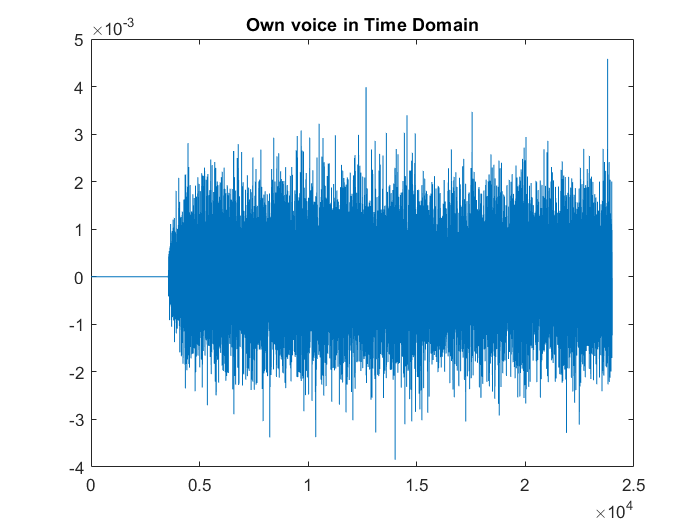

voice_vector=getaudiodata(myvoice);
figure(1)
plot(voice_vector)
title('Own voice in Time Domain');

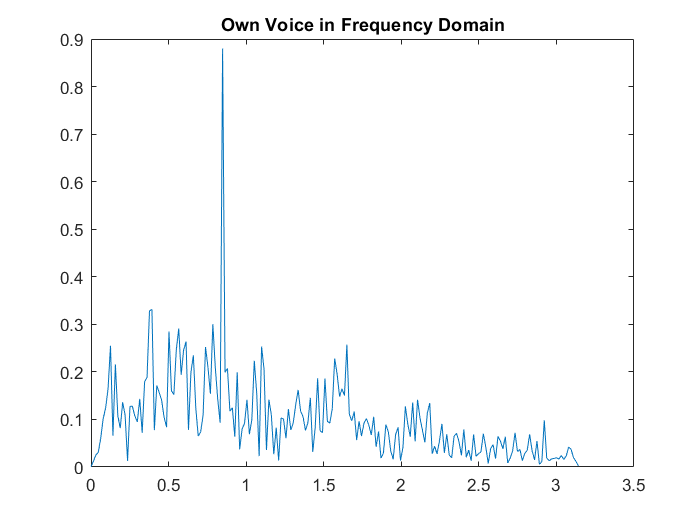


%x = fft(voice_vector);
%figure(2)
%plot(x)
w=0:pi/200:pi; 
[h w]=freqz(voice_vector,1,w);
figure(2)
plot(w,abs(h))
title('Own Voice in Frequency Domain')


with_noise1=awgn(voice_vector,99);% Noice
snr = 99

snr = 99

with_noise2=awgn(voice_vector,20);% Noise 
snr = 20

snr = 20

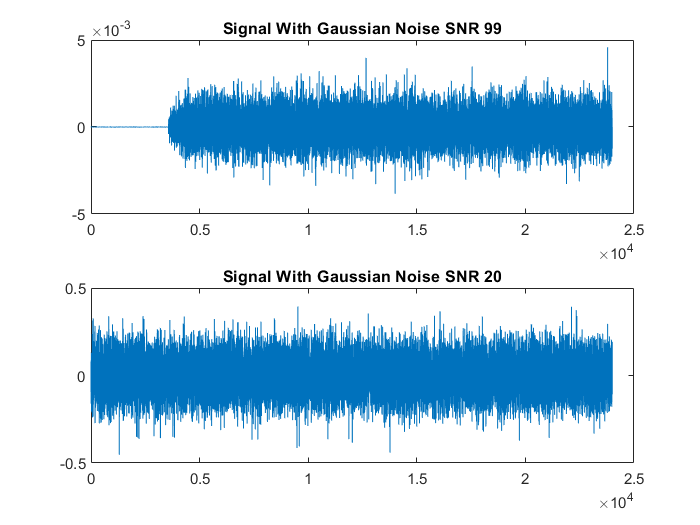

figure(3)
subplot(211)
plot(with_noise1)
title('Signal With Gaussian Noise SNR 99')
subplot(212)
plot(with_noise2)
title('Signal With Gaussian Noise SNR 20')

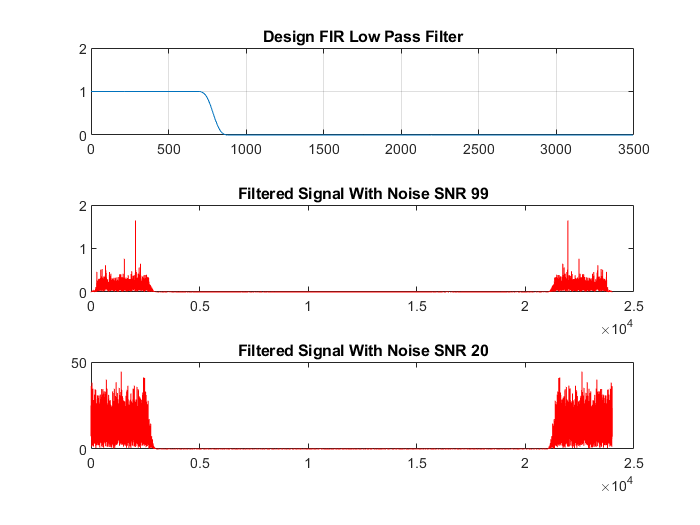


F1=8000;
F2=800;
F3=1000;
r1=2;
r2=60;
p1=1-10.^(-r1/20);
s1=10.^(-r2/20);
FF=[F2 F3];
ma=[1 0];
v=[p1 s1];
[A21,wA21,bt,Yp]=kaiserord(FF,ma,v,F1);
lowpassfilter=fir1(A21,wA21,kaiser(A21+1,bt));
[h,w]=freqz(lowpassfilter,1);
figure(4);
subplot(311)
plot(w*7000*0.5/pi,abs(h));
ylim([0,2])
title('Design FIR Low Pass Filter','fontweight','bold');grid;
Signal_1=fftfilt(lowpassfilter,with_noise1);
sound(Signal_1,F1);
sound(Signal_1);
signal1=fft(Signal_1);
subplot(312)
plot(abs(signal1),'r');
title('Filtered Signal With Noise SNR 99');
Signal_2=fftfilt(lowpassfilter,with_noise2);
sound(Signal_2,F1);
sound(Signal_2);
signal2=fft(Signal_2);
subplot(313)
plot(abs(signal2),'r');
title('Filtered Signal With Noise SNR 20');

F1=8000;
F=[1000 1300 2210 2410]

F =         1000        1300        2210        2410


ma=[0 1 0];
devs=[0.01 0.05 0.01];
[n,wA23,bt,Yp]=kaiserord(F,ma,devs,F1);
n=n+rem(n,2)

n = 90

bandpassfilter=fir1(n,wA23,'bandpass',kaiser(n+1,bt),'noscale');
[h,w]=freqz(bandpassfilter,1,1024,F1);
figure(6)
subplot(311)
plot(w*10000*0.5/pi,abs(h));
title('DESIGN FIR BAND PASS FILTER','fontWeight','bold');
grid;
signal_5=fftfilt(bandpassfilter,with_noise1)

signal_5 =    -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


sound(signal_5,F1);
sound(signal_5);
signal_5=fft(signal_5)

signal_5 =   -0.0001 + 0.0000i
  -0.0001 + 0.0000i
  -0.0001 + 0.0000i
  -0.0001 - 0.0000i
  -0.0001 - 0.0000i
  -0.0001 + 0.0000i
  -0.0001 - 0.0000i
  -0.0001 - 0.0000i
  -0.0001 + 0.0000i
  -0.0001 + 0.0000i


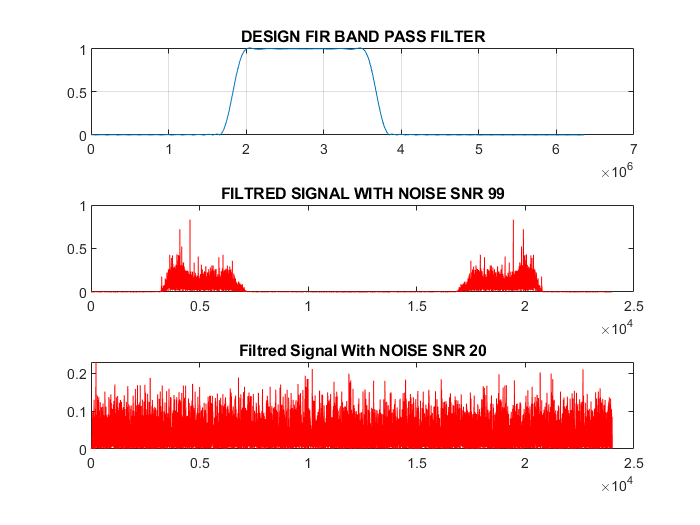

subplot(312)
plot(abs(signal_5),'r');
title('FILTRED SIGNAL WITH NOISE SNR 99');
signal_6=fftfilt(bandpassfilter,with_noise2);
sound(signal_6);
subplot(313)
plot(abs(signal_6),'r');
title('Filtred Signal With NOISE SNR 20');